# Configuration Space: Part 1 of 2

## INTRODUCTION

The primary objective of the Configuration Space programming assignment is to provide the students with experience in practical application of Configuration Space usage in real world environments.  In this programming assignment, you will be writing a program to help guide a two link robotic arm from one configuration space to another while avoiding obstacles in the workspace. The purpose of this assignment is to provide you with some experience working with representation of configuration space. The configuration of the robot is captured by two joint angles, *θ*1 and *θ*2, as shown in Figure 1. These angles are represented with values between 0 to 360 degrees.

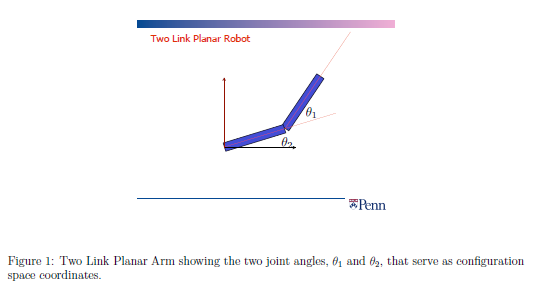

In Figure 2, the left image shows a graph depicting the robot and the workspace obstacles and the right image shows a plot of the corresponding configuration space (White) and configuration space obstacles (Black). The horizontal and vertical axes correspond to *θ*1 and *θ*2 respectively. In the left graph, both the robot and the obstacles are represented by a collection of triangles. This decomposition of the robot (and obstacles) into triangles helps us in deciding if a particular robotic configuration would lead to a collision or not, by checking whether any of the triangles in the robot intersect any of the triangles in the obstacles.

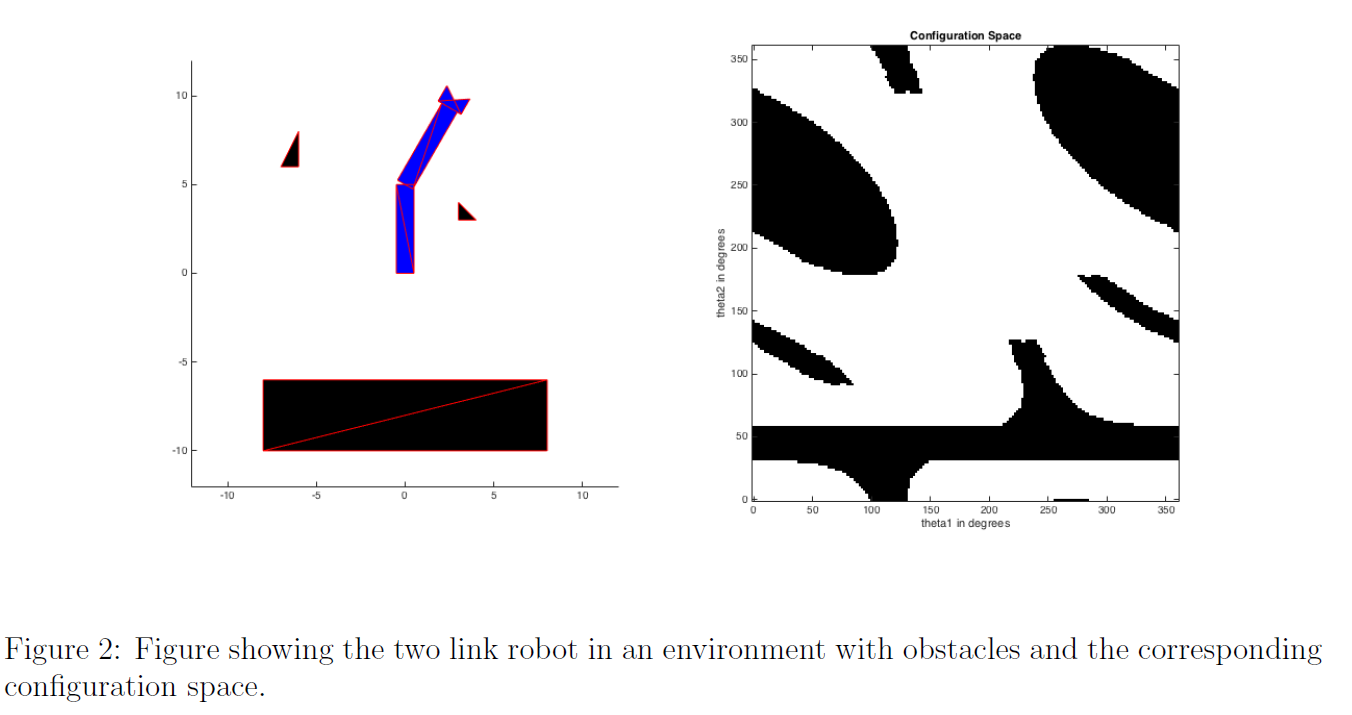

## **INTERSECTION OF TRIANGLES**

For this particular assignment, since the robotic arm and the obstacles are assumed to be a collection of triangles, any form of real world collision is simplified to the fact of intersection between the triangles of the robotic arm and the obstacle. 

One of the many approaches towards understanding this concept is to consider all the 6 edges (3 for each triangle) and whether they act as separating lines where all verticesof one triangle lie on one side and all vertices of other triangle on the other side.

Also, the possible scenarios to check for are as follows:

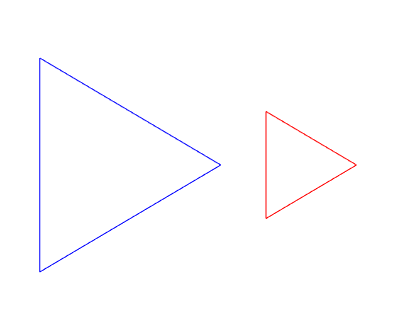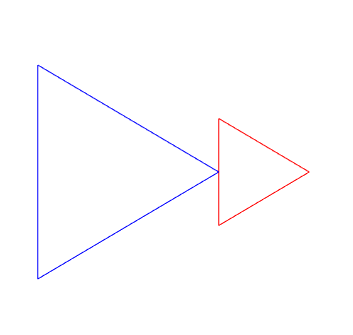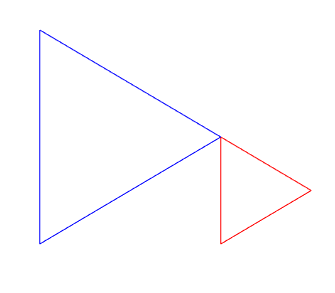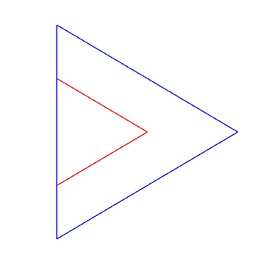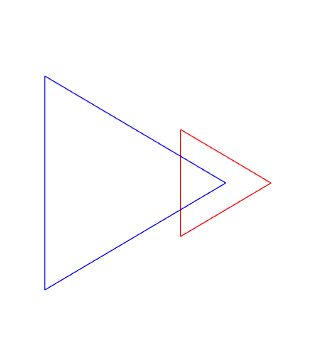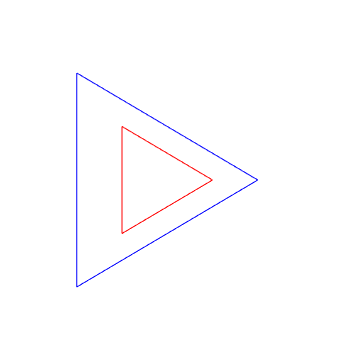

Moving from left to right, the possible scenarios include:

    1) Non intersecting triangles

    2) Triangles intersecting at a single point (one line - one point)

    3) Triangles intersecting at a single point (one point - one point)

    4) Triangles intersecting via line overlap

    5) Triangles intersecting at multiple points

    6) One triangle overlapping the other

## **FUNCTION DESCRIPTION**

For this part of the assignment you have to create the function `triangle_intersection` with the following input and output arguments:

- `P1`**, **`P2`: a `3x2` array (each), describing the vertices of a triangle, where the first column represents `x` coordinates and the second column represents `y` coordinates.

- `flag`: Return value for the function, set to true if determines intersection (including overlapping) between triangles and false otherwise.

Once completed, you can try out multiple scearios to check if your algorithm works for all cases as discussed above.

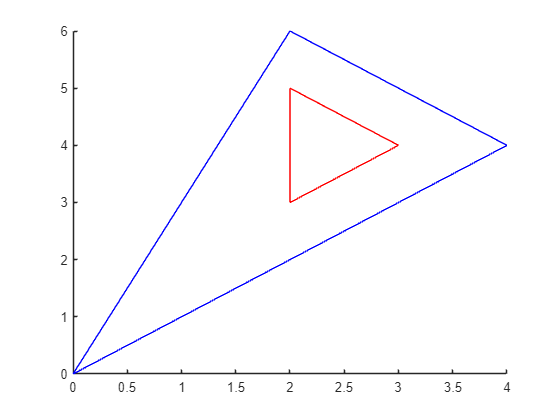

x = [2, 2, 3]; 
y = [5, 3, 4];
P1 = [x; y]';

x = [0, 4, 2];
y = [0, 4, 6];
P2 = [x; y]';

line([P1(:, 1)' P1(1, 1)], [P1(:, 2)' P1(1, 2)], 'Color', 'r')
line([P2(:, 1)' P2(1, 1)], [P2(:, 2)' P2(1, 2)], 'Color', 'b')


flag = triangle_intersection(P1, P2);
if flag == 1
    disp("Intersection")
else
    disp("No Intersection")
end

Intersection


function flag = triangle_intersection(P1, P2)
    % triangle_test : returns true if the triangles overlap and false otherwise
    
    %%% All of your code should be between the two lines of stars.
    % *******************************************************************

    flag = false; 

    for i = 1:3
        for j = 1:3
            if i >= 3
                ii = 1;
            else
                ii = i + 1;
            end

            if j >= 3
                jj = 1;
            else
                jj = j + 1;
            end

            x1 = P1(i , 1);
            x2 = P1(ii, 1);
            y1 = P1(i , 2);
            y2 = P1(ii, 2);

            x3 = P2(j , 1);
            x4 = P2(jj, 1);
            y3 = P2(j , 2);
            y4 = P2(jj, 2);      

            if line_intersection(x1, x2, x3, x4, y1, y2, y3, y4) == 1
                flag = true;
            end
        end
    end

    if triangle_inside(P1,P2)
        flag = true;
    end  
        
    function [ intersection ] = line_intersection( x1, x2, x3, x4, y1, y2, y3, y4)
        denom  = (y4-y3) * (x2-x1) - (x4-x3) * (y2-y1);
        numera = (x4-x3) * (y1-y3) - (y4-y3) * (x1-x3);
        numerb = (x2-x1) * (y1-y3) - (y2-y1) * (x1-x3);
    
        % Are the line coincident? 
        if abs(numera) < eps && abs(numerb) < eps && abs(denom) < eps
            intersection = true;
        else
            % Are the line parallel 
            if abs(denom) < eps
                intersection = false;
            else
                % Is the intersection along the the segments 
                mua = numera / denom;
                mub = numerb / denom;

                if mua < 0 || mua > 1 || mub < 0 || mub > 1
                    intersection = false;
                else
                    intersection = true;
                end
            end
        end   
    end
    
    function [inside] = triangle_inside(P1, P2)
        %UNTITLED3 Summary of this function goes here
        %   Detailed explanation goes here
        inside = false;
        
        B = [P2(1, 1) P2(1, 2) 1;
             P2(2, 1) P2(2, 2) 1;
             P2(3, 1) P2(3, 2) 1];
        
        B1 = [P1(1, 1) P1(1, 2) 1;
              P2(2, 1) P2(2, 2) 1;
              P2(3, 1) P2(3, 2) 1];
    
        B2 = [P2(1, 1) P2(1, 2) 1;
              P1(1, 1) P1(1, 2) 1;
              P2(3, 1) P2(3, 2) 1];
    
        B3 = [P2(1, 1) P2(1, 2) 1;
              P2(2, 1) P2(2, 2) 1;
              P1(1, 1) P1(1, 2) 1];
        
        b = abs(det(B1)/2) + abs(det(B2)/2) + abs(det(B3)/2);
        
        if abs(det(B)/2) == b
            inside = true;
        end
    end
% *******************************************************************
end